G = zpk([], [-1, -1], 1);   % 零極點增益(s)模型，在 = -1zpk時具有雙極點
C = pid(2, 1.3, 0.3, 0.5);  % PID控制器
S = tf(5, [1 4]);           % 傳遞函數
F = tf(1, [1 1]);           % 傳遞函數

% 建立開環響應SGC
open_loop = S*G*C;

% 建立未過濾的閉迴路響應模型
T = feedback(G*C, S);

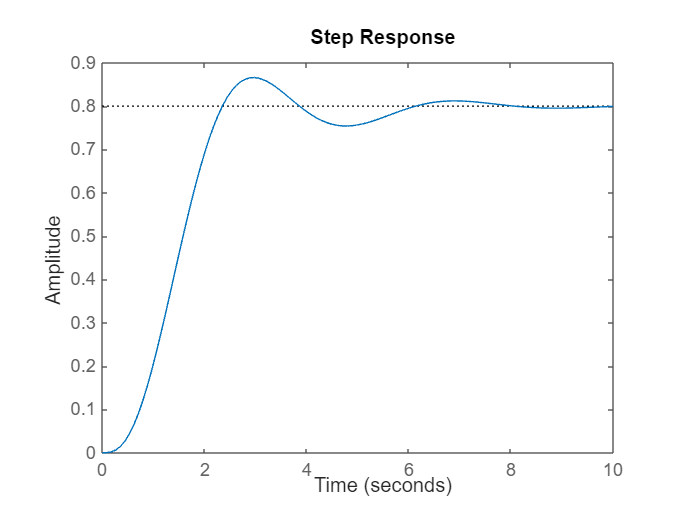

Try = T * F; % 加入過濾器

stepplot(Try);


num = [1 0];        % Numerator: s
den = [1 2 10];     % Denominator: s^2 + 2s + 10
H = tf(num, den)

H =
 
        s
  --------------
  s^2 + 2 s + 10
 
Continuous-time transfer function.
Model Properties


s = tf('s');        % 建立拉普拉斯轉換
H = s / (s^2 + 2*s + 10)

H =
 
        s
  --------------
  s^2 + 2 s + 10
 
Continuous-time transfer function.
Model Properties


% 創建ZPK模型

z = 0;              % 零
p = [2 1+1i 1-1i];  % 極數
k = -2;             % 增益
H = zpk(z, p, k)

H =
 
          -2 s
  --------------------
  (s-2) (s^2 - 2s + 2)
 
Continuous-time zero/pole/gain model.
Model Properties


s = tf('s');       
H = -2*s / (s - 2) / (s^2 + 2*s + 10)

H =
 
       -2 s
  --------------
  s^3 + 6 s - 20
 
Continuous-time transfer function.
Model Properties
